# Znajdowanie parametrów teczówki 

# - w 'naturalnym' oświetleniu

Zuzanna Rudnicka

249533

Antoni Bezdzietny

249327

#### Przygotowanie ścieżki do zdjęcia.

clear all;
addpath("scripts\")
set_default = true;
            
image_folder = "database/image_cz/";
eye         = "001" ;
eye_side    = "L_";
eye_variant = "2";
image_path = strcat(image_folder,eye,eye_side,eye_variant,".png");

#### Wczytanie zdjęcia.

img_raw    = imread(image_path); 
img_rgb    = imresize(img_raw, size(img_raw,1:2)*0.5);
img_gray   = rgb2gray(img_rgb);

#### Wczytanie domyślnych wartości

addpath("database\image_cz\parameters");
mfile = dir(strcat("database\image_cz\parameters\s", ...
    eye,eye_side,eye_variant,"*.m"));

if isempty(mfile)
    mfile = dir(strcat("database\image_cz\parameters\def*.m"));
end
[trash, name] = fileparts(mfile(1).name);
run(name);

#### Wyświetlenie przetwarzanych obrazów w rgb i odcieniach szarości.

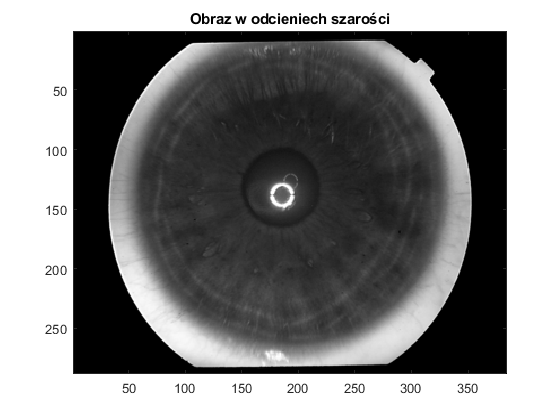

imagesc(img_gray);
title("Obraz w odcieniech szarości");
colormap("gray");

#### Detekcja krawędzi metoda Canny.

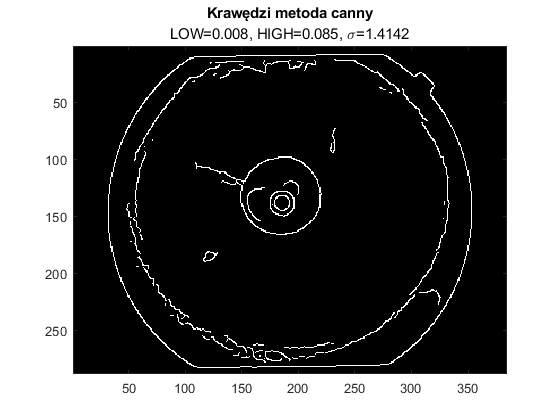

canny_tresh_low  = 0.034;
canny_tresh_high = 0.095;
canny_sigma      = 5.2142;
canny_tresh_low = isDefault(set_default,def_canny_tresh_low,canny_tresh_low);
canny_tresh_high = isDefault(set_default,def_canny_tresh_high,canny_tresh_high);
canny_sigma = isDefault(set_default,def_canny_sigma,canny_sigma);


img_edge = edge(img_gray,"canny",[canny_tresh_low canny_tresh_high], canny_sigma);
imagesc(img_edge);
title("Krawędzi metoda canny", ...
    "LOW="+num2str(canny_tresh_low)+", HIGH="+num2str(canny_tresh_high)+", \sigma="+num2str(canny_sigma));

#### Wyszukiwanie okręgów wykorzystując transformatę kołową Hougha.

- `Wyszukiwanie okręgu odbicia oświetlenia.`

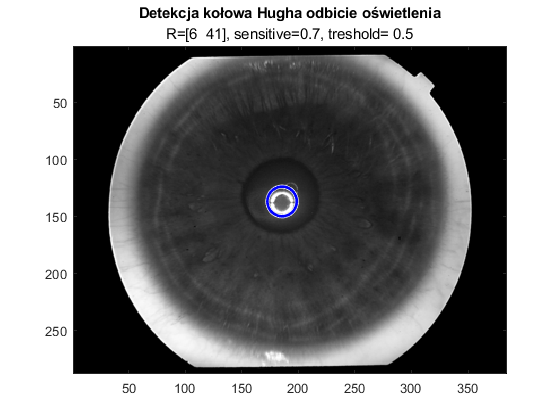

polarity_light      = "bright";
low_radius_light    =6 ;
hight_radius_light  =46 ;
sensitive_light     = 0.7;
treshold_light      = 0.5;

polarity_light = isDefault(set_default,def_polarity_light,polarity_light);
low_radius_light = isDefault(set_default,def_low_radius_light,low_radius_light);
hight_radius_light = isDefault(set_default,def_hight_radius_light,hight_radius_light);
sensitive_light = isDefault(set_default,def_sensitive_light,sensitive_light);
treshold_light = isDefault(set_default,def_treshold_light,treshold_light);

[centers_light,radii_light,metric_light] = imfindcircles(img_edge, ...
    [low_radius_light hight_radius_light],'ObjectPolarity',polarity_light, ...
    'Sensitivity',sensitive_light,"EdgeThreshold",treshold_light,"Method","TwoStage");

imagesc(img_gray);
viscircles(centers_light, radii_light,'EdgeColor','b');
title("Detekcja kołowa Hugha odbicie oświetlenia", ...
    "R=["+num2str(low_radius_light)+"  "+num2str(hight_radius_light)+"], sensitive=" ...
    +num2str(sensitive_light)+", treshold= "+num2str(treshold_light));

- `Wyszukiwanie granicy źrenica-tęczówka.`

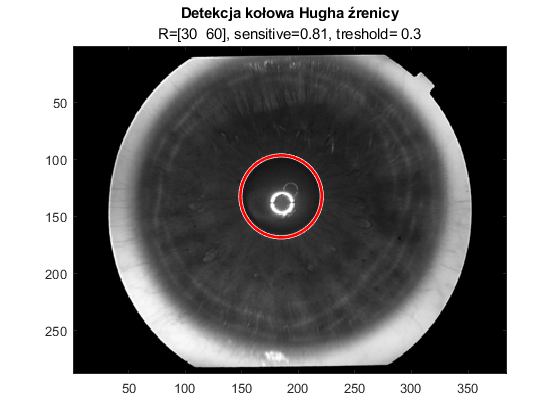

polarity_pupil      = "bright";
low_radius_pupil    =35 ;
hight_radius_pupil  =65 ;
sensitive_pupil     = 0.91;
treshold_pupil      = 0.3;

polarity_pupil = isDefault(set_default,def_polarity_pupil,polarity_pupil);
low_radius_pupil = isDefault(set_default,def_low_radius_pupil,low_radius_pupil);
hight_radius_pupil = isDefault(set_default,def_hight_radius_pupil,hight_radius_pupil);
sensitive_pupil = isDefault(set_default,def_sensitive_pupil,sensitive_pupil);
treshold_pupil = isDefault(set_default,def_treshold_pupil,treshold_pupil);

[centers_pupil,radii_pupil,metric_pupil] = imfindcircles(img_edge, ...
    [low_radius_pupil hight_radius_pupil],'ObjectPolarity',polarity_pupil, ...
    'Sensitivity',sensitive_pupil,"EdgeThreshold",treshold_pupil,"Method","TwoStage");

position_closest_pupil = findMinDistance(centers_pupil,centers_light);

imagesc(img_gray);
viscircles(centers_pupil(position_closest_pupil,:), radii_pupil(position_closest_pupil,:),'EdgeColor','r');
title("Detekcja kołowa Hugha źrenicy", ...
    "R=["+num2str(low_radius_pupil)+"  "+num2str(hight_radius_pupil)+"], sensitive=" ...
    +num2str(sensitive_pupil)+", treshold= "+num2str(treshold_pupil));

- `Wyszukiwanie granicy tęczówka-białko.`

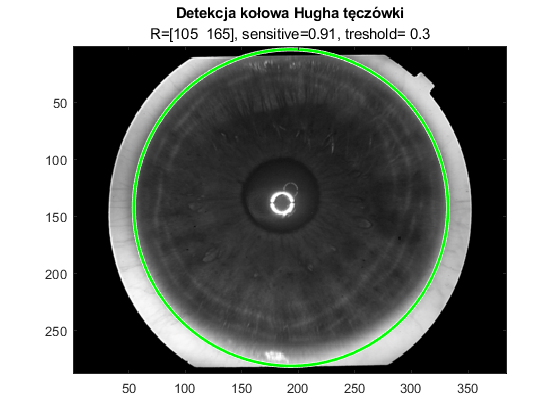

polarity_iris       = "bright";
low_radius_iris     =100 ;
hight_radius_iris   =150 ;
sensitive_iris      = 0.94;
treshold_iris       = 0.3;

polarity_iris = isDefault(set_default,def_polarity_iris,polarity_iris);
low_radius_iris = isDefault(set_default,def_low_radius_iris,low_radius_iris);
hight_radius_iris = isDefault(set_default,def_hight_radius_iris,hight_radius_iris);
sensitive_iris = isDefault(set_default,def_sensitive_iris,sensitive_iris);
treshold_iris = isDefault(set_default,def_treshold_iris,treshold_iris);

[centers_iris,radii_iris,metric_iris] = imfindcircles(img_edge, ...
    [low_radius_iris hight_radius_iris],'ObjectPolarity',polarity_iris, ...
    'Sensitivity',sensitive_iris,"EdgeThreshold",treshold_iris,"Method","TwoStage");

position_closest_iris = findMinDistance(centers_iris,centers_light);

imagesc(img_gray);
viscircles(centers_iris(position_closest_iris,:), radii_iris(position_closest_iris,:),'EdgeColor','g');
title("Detekcja kołowa Hugha tęczówki", ...
    "R=["+num2str(low_radius_iris)+"  "+num2str(hight_radius_iris)+"], sensitive=" ...
    +num2str(sensitive_iris)+", treshold= "+num2str(treshold_iris));

#### Wykryte granice

- W odcieniach szarości

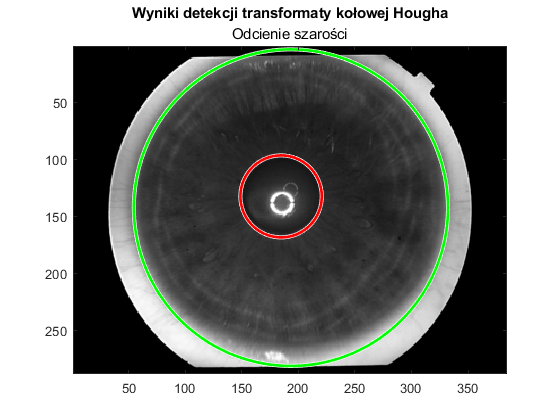

imagesc(img_gray);
viscircles(centers_pupil(position_closest_pupil,:), radii_pupil(position_closest_pupil,:),'EdgeColor','r');
viscircles(centers_iris(position_closest_iris,:), radii_iris(position_closest_iris,:),'EdgeColor','g');
title("Wyniki detekcji transformaty kołowej Hougha","Odcienie szarości");

- W RGB

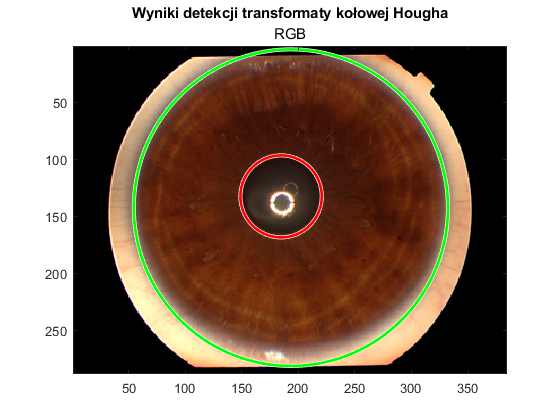

imagesc(img_rgb);
viscircles(centers_pupil(position_closest_pupil,:), radii_pupil(position_closest_pupil,:),'EdgeColor','r');
viscircles(centers_iris(position_closest_iris,:), radii_iris(position_closest_iris,:),'EdgeColor','g');
title("Wyniki detekcji transformaty kołowej Hougha","RGB");

#### `Normalizacja `rubber sheet model.

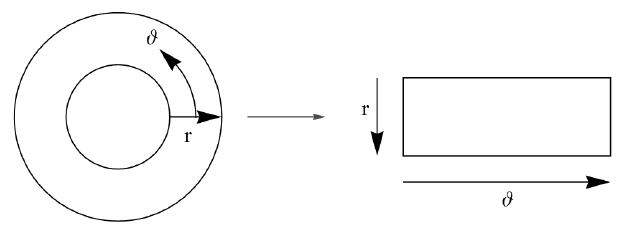

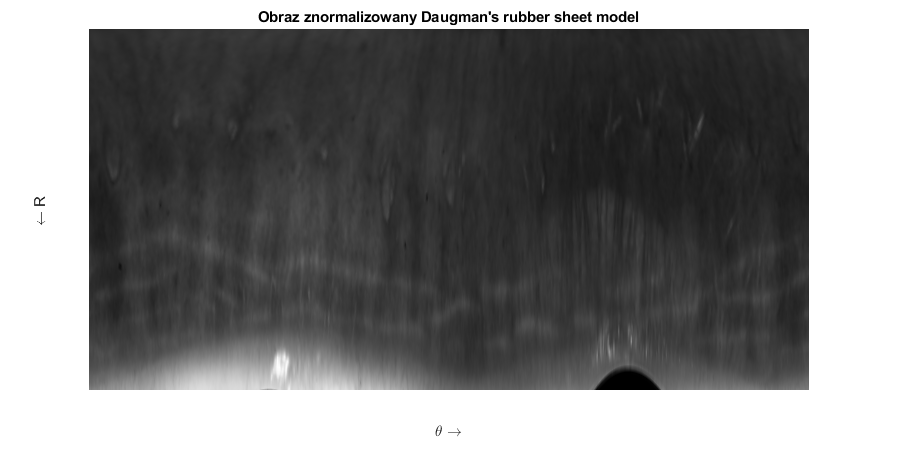

if not(isempty(centers_iris) || isempty(centers_pupil) || isempty(centers_light))
    rubber = rubberSheetNormalisation(img_gray,centers_pupil(position_closest_pupil,1),centers_pupil(position_closest_pupil,2), radii_pupil(position_closest_pupil,:), ...
    centers_iris(position_closest_iris,1), centers_iris(position_closest_iris,2), radii_iris(position_closest_iris,:));
    rubber = rubber';
    imshow(rubber);
    title("Obraz znormalizowany Daugman's rubber sheet model");
    xlabel("\theta \rightarrow");
    ylabel("\leftarrow R ")
end

#### Gabor filter.

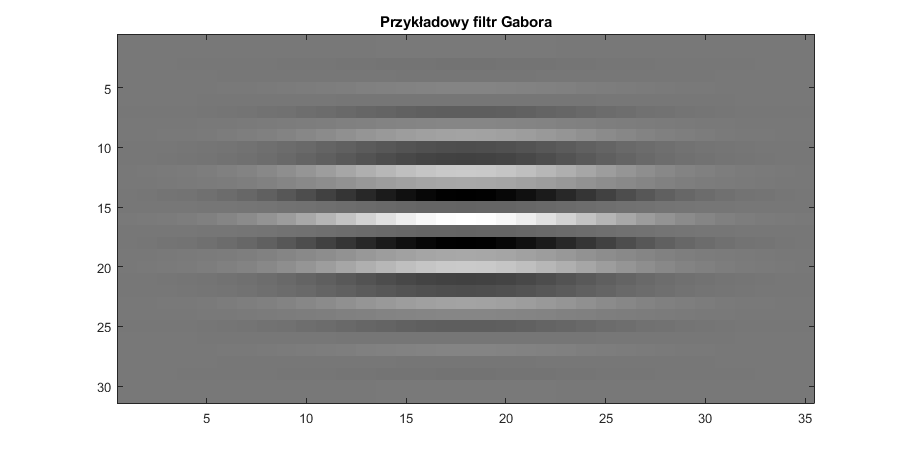

gabor_filter = gabor_fn(5,pi/2,pi/4,0.0,0.9);
imagesc(gabor_filter);
title("Przykładowy filtr Gabora");

#### Add Gabor filter.

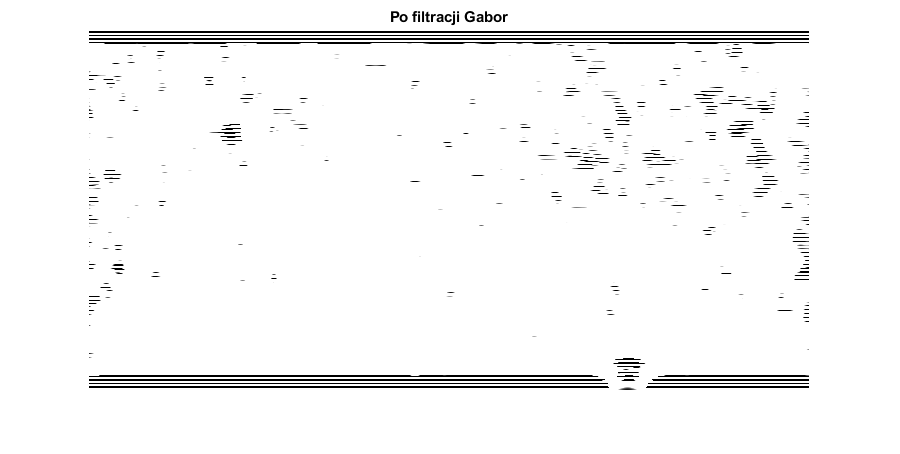

img_filter = filter2(gabor_filter,rubber);
imshow(img_filter);
title("Po filtracji Gabor");

set_default = false;